## Quantum Teleportation

Let's now make quantum teleportation!

We need a quantum circuit with 2 qubits for Alice's side, and 1 qubit for Bob's side:

qc = quantumCircuit(3, Name="Quantum_Teleportation")

qc =   quantumCircuit with properties:

    NumQubits: 3
        Gates: [0×1 quantum.gate.QuantumGate]
         Name: "Quantum_Teleportation"


We will use the following notation:

- qubit 1 is the qubit to teleport from Alice to Bob

- qubits 2 and 3 are the two entangled qubits: Alice owns 2 and Bob owns 3

We need to entangle qubits 2 and 3. To do that, we need to apply a Hadamard gate to qubit 2 and a CNOT gate controlled by and applied to 3:

h_gate = hGate(2)

h_gate =   SimpleGate with properties:

             Type: "h"
    ControlQubits: [1×0 double]
     TargetQubits: 2
           Angles: [1×0 double]


cnot_gate = cxGate(2, 3)

cnot_gate =   SimpleGate with properties:

             Type: "cx"
    ControlQubits: 2
     TargetQubits: 3
           Angles: [1×0 double]


gates = [h_gate, cnot_gate]

gates =   1×2 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    h                2     
       2    cx     2         3     


qc.Gates = gates

qc =   quantumCircuit with properties:

    NumQubits: 3
        Gates: [2×1 quantum.gate.SimpleGate]
         Name: "Quantum_Teleportation"


Now, we can create a custom state for qubit 1.

Two possible ways:

- We apply gates to qubit 1 until we reach the desired state

- We specifiy an initialization state for qubit 1 before simulation

We will proceed with method #1. We will use a rotation around Z of 90°: $\ket{\psi_A} == X\ket{0} == \ket{1} $

x_gate = xGate(1)

x_gate =   SimpleGate with properties:

             Type: "x"
    ControlQubits: [1×0 double]
     TargetQubits: 1
           Angles: [1×0 double]


qc.Gates(end + 1) = x_gate

qc =   quantumCircuit with properties:

    NumQubits: 3
        Gates: [3×1 quantum.gate.SimpleGate]
         Name: "Quantum_Teleportation"


We can now proceed with measurement.

Let's run a simulation and see what basis states we get:

S = simulate(qc, "000")

S =   QuantumState with properties:

    BasisStates: [8×1 string]
     Amplitudes: [8×1 double]
      NumQubits: 3


str = formula(S)

str =     "0.70711 * |100> +
     0.70711 * |111>"


We achieved the following formula:


$$\ket{\psi_A}\ket{\Phi_{AB}^+} = 0.707\ket{100} ++  0.707 \ket{111}$$


which can be also written as:


$$\ket{\psi_A}\ket{\Phi_{AB}^+} = \frac{1}{2}( \frac{\ket{01}++\ket{10}}{\sqrt{2}} - \frac{\ket{01}--\ket{10}}{\sqrt{2}})\ket{0} ++ \frac{1}{2}(\frac{\ket{00}++\ket{11}}{\sqrt{2}} - \frac{\ket{00}--\ket{11}}{\sqrt{2}})\ket{1}$$


which becomes:


$$\ket{\psi_A}\ket{\Phi_{AB}^+} = \frac{1}{2}( \Phi_{AB}^+ \ket{1} -- \Phi_{AB}^- \ket{1}++ \Psi_{AB}^+ \ket{1} -- \Psi_{AB}^- \ket{1}))$$


which finally becomes:


$$\ket{\psi_A}\ket{\Phi_{AA'}^+} = \frac{1}{2}( \Phi_{AA'}^+ \ket{1} ++ \Phi_{AA'}^-Z \ket{1}++ \Psi_{AA'}^+ X\ket{1} ++ \Psi_{AA'}^-XZ \ket{1}))$$


As we can see, Bob's qubit now contains $\ket{\psi}$.

Unfortunately, we cannot simulate a measurement with Bell basis. 

Let's assume Alice measures and gets $\ket{\Psi_{AA'}^-}$.  She will send "11" as two classical bits to Bob, who will undestand that he needs to apply gates XZ to his qubit:

qc.Gates(end + 1) = zGate(3); 
qc.Gates(end + 1) = xGate(3)

qc =   quantumCircuit with properties:

    NumQubits: 3
        Gates: [5×1 quantum.gate.SimpleGate]
         Name: "Quantum_Teleportation"


Notice that, to apply XZ as a matrix product, we first insert Z gate, and then apply X gate to its result (gates follow inverse order with respect to the matrix formalism)

We can now finally plot the circuit:

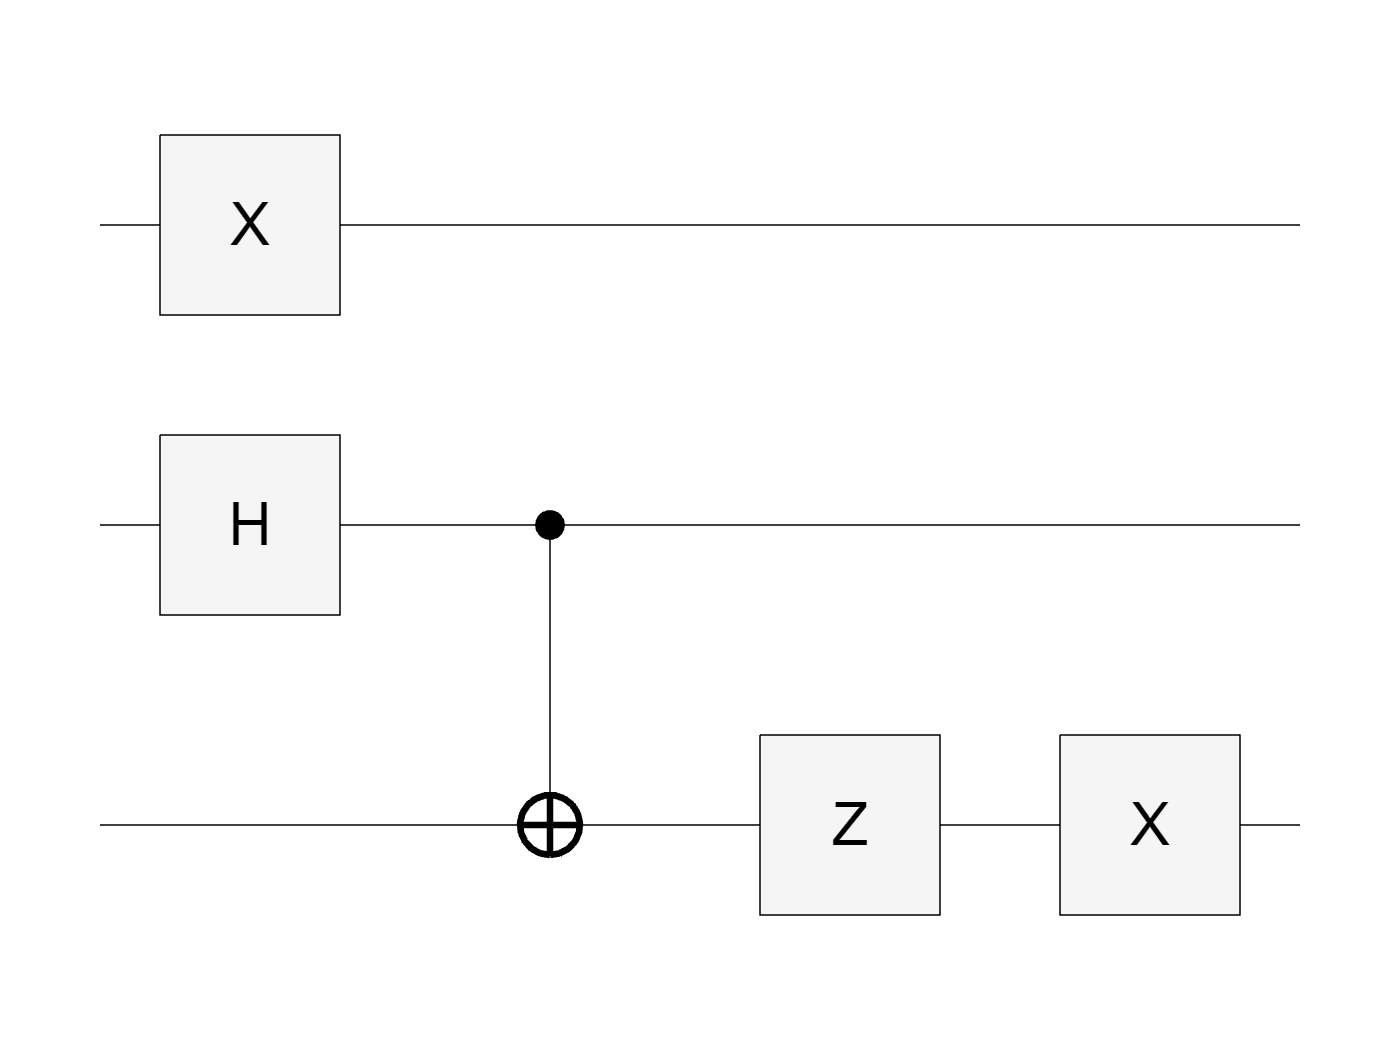

qc.plot()